# Ce script dépend pour le moment du script AnalyseEtudeParam

Objectif de ce script :

- importer une structure propre issu des autres script OK

- Afficher tous les résultats de simulation comme sur TRNSys OK

- Tempérrature ext VS int OK

- Consommation (sur le même plot avec un 3eme axe) FORGET IT, I'VE DONE BETTER

- Summary annuel qui je pense est aussi à importer depuis les résultat dans les dossiers ou che pas trop NOT URGENT

- Exploitation des résultats spécifiques genre la figure pour montrer les résultats de l'analyse paramétrique OK

- Ne pas te contenter de ce qui est demandé par tes encadrantes, fais mieux, avec tes idées, tu en es capable ;-)

- Go Go Go

- Tu a bcp de choses à faire mais sache prioriser les tâches !!!

### Rappel de la façon d'accéder au données stockées dans une structure

% TheStructure = TTDataStruct;
% DataNameInsideStruct = fieldnames(TheStructure);
% DataNumero2Toextract = TheStructure.(DataNameInsideStruct{2}) % Ce numero 2 peut ensuite être remplacé par i et utilisé dans un boucle


### Import de la structure

NomDuFichierExterne = "C:\Users\tafit\OneDrive\Documents\1_These\16-Github\Modelisation\TRNSys\Simulation_Finie\20250610_Simulation_7ans_TLS_avec_15prs\Mal_isole\Simulation7ans_MalIsole_avec_15prs.mat";

load(NomDuFichierExterne)

TheStructure = TTDataStruct;

DataNameInsideStruct = fieldnames(TheStructure)

DataNameInsideStruct = 7×1 cell array
    {'DataDossier1'}
    {'DataDossier2'}
    {'DataDossier3'}
    {'DataDossier4'}
    {'DataDossier5'}
    {'DataDossier6'}
    {'DataDossier7'}


    {'DataDossier1'}



DatasetOut = 8760×8 timetable
            Time            TRNSys_TIME    Temperature_ext_C    Temperature_int_C    Temperature_op_C    QHeat_kJ_h    QHeat_kWh    QCool_kJ_h    QCool_kWh
    ____________________    ___________    _________________    _________________    ________________    __________    _________    __________    _________

    01-Jan-2024 01:00:00         1                9.06                   20                   20                0             0         0             0    
    01-Jan-2024 02:00:00         2                8.93                   20               19.772             1190       0.33056         0             0    
    <

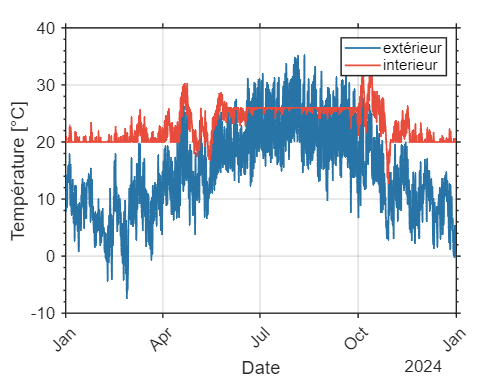

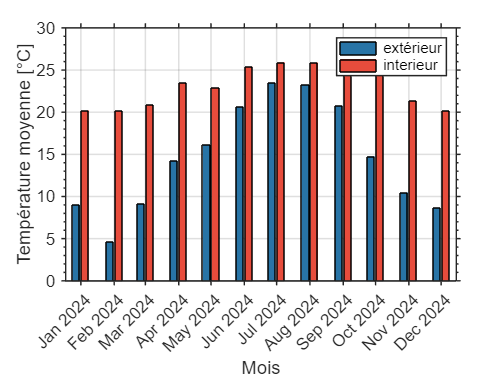

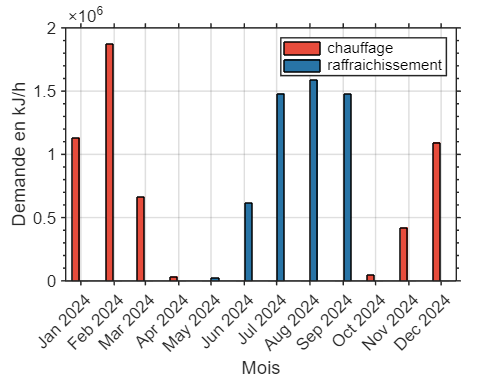

NbJofHeating = 155

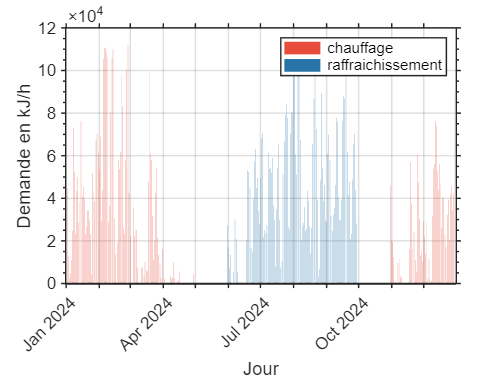

    {'DataDossier2'}



DatasetOut = 8760×8 timetable
            Time            TRNSys_TIME    Temperature_ext_C    Temperature_int_C    Temperature_op_C    QHeat_kJ_h    QHeat_kWh    QCool_kJ_h    QCool_kWh
    ____________________    ___________    _________________    _________________    ________________    __________    _________    __________    _________

    01-Jan-2024 01:00:00         1               -0.12                 20                     20                0             0         0             0    
    01-Jan-2024 02:00:00         2              -0.015                 20                 19.644           2050.5        0.5696         0             0    
    <

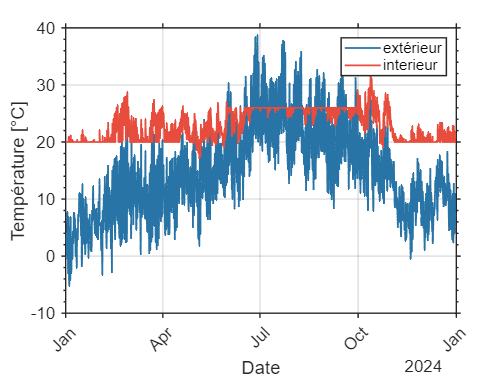

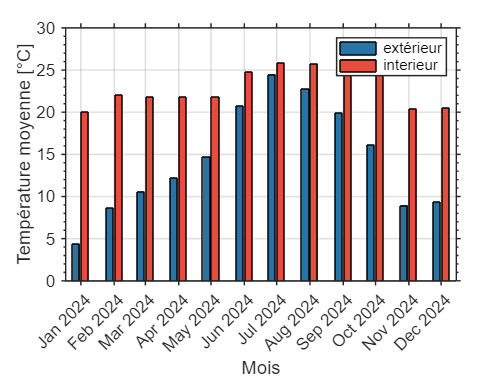

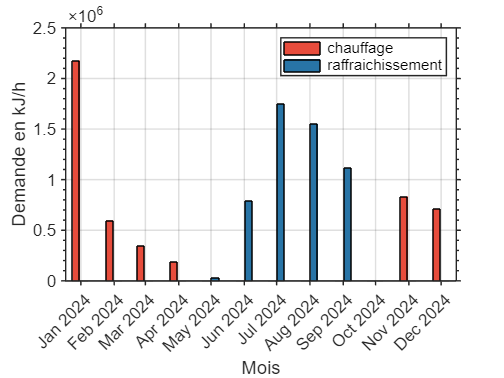

NbJofHeating =    155   151


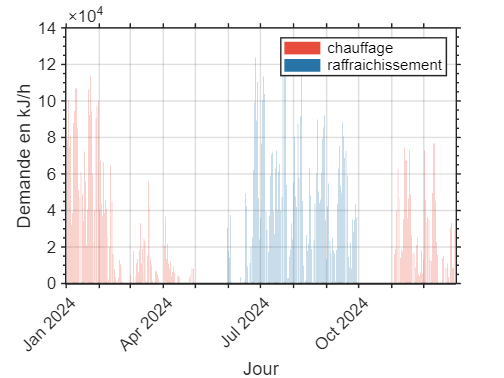

    {'DataDossier3'}



DatasetOut = 8760×8 timetable
            Time            TRNSys_TIME    Temperature_ext_C    Temperature_int_C    Temperature_op_C    QHeat_kJ_h    QHeat_kWh    QCool_kJ_h    QCool_kWh
    ____________________    ___________    _________________    _________________    ________________    __________    _________    __________    _________

    01-Jan-2024 01:00:00         1                7.12                 20                     20                0             0         0             0    
    01-Jan-2024 02:00:00         2               7.145                 20                 19.778           1269.9       0.35274         0             0    
    <

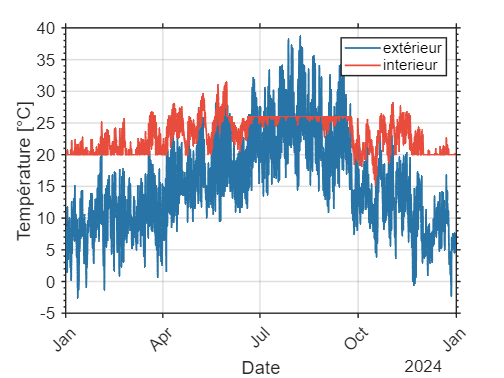

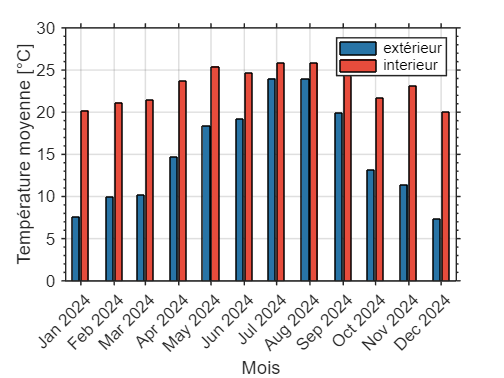

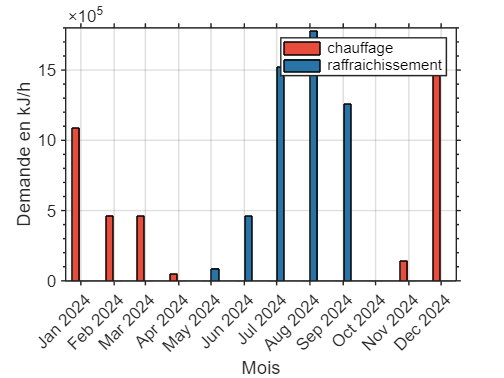

NbJofHeating =    155   151   127


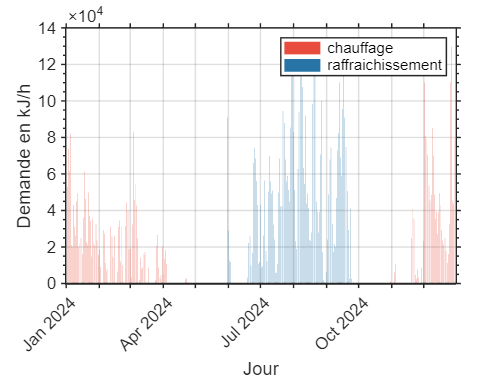

    {'DataDossier4'}



DatasetOut = 8760×8 timetable
            Time            TRNSys_TIME    Temperature_ext_C    Temperature_int_C    Temperature_op_C    QHeat_kJ_h    QHeat_kWh    QCool_kJ_h    QCool_kWh
    ____________________    ___________    _________________    _________________    ________________    __________    _________    __________    _________

    01-Jan-2024 01:00:00         1                5.96                 20                     20                0             0         0             0    
    01-Jan-2024 02:00:00         2               5.645                 20                 19.732           1483.3       0.41202         0             0    
    <

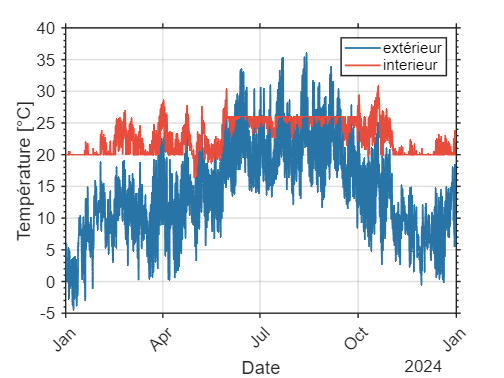

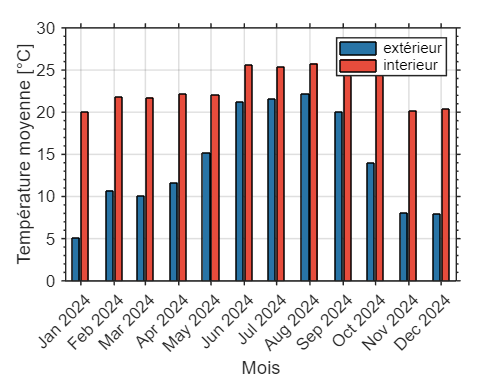

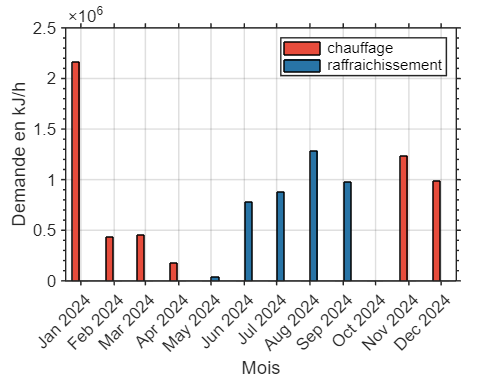

NbJofHeating =    155   151   127   151


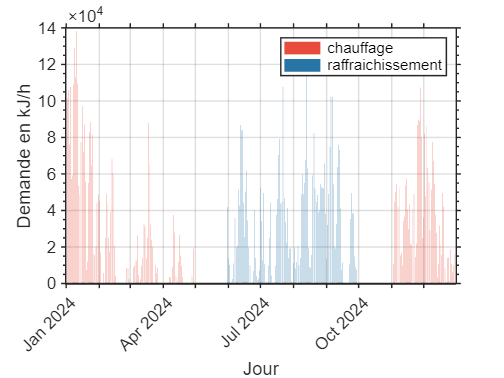

    {'DataDossier5'}



DatasetOut = 8760×8 timetable
            Time            TRNSys_TIME    Temperature_ext_C    Temperature_int_C    Temperature_op_C    QHeat_kJ_h    QHeat_kWh    QCool_kJ_h    QCool_kWh
    ____________________    ___________    _________________    _________________    ________________    __________    _________    __________    _________

    01-Jan-2024 01:00:00         1                5.49                   20                   20                0             0         0             0    
    01-Jan-2024 02:00:00         2               5.035                   20               19.713           1571.5       0.43653         0             0    
    <

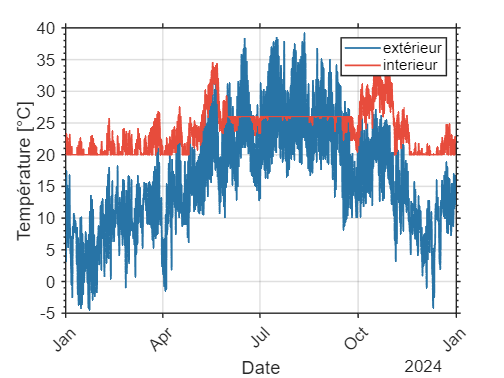

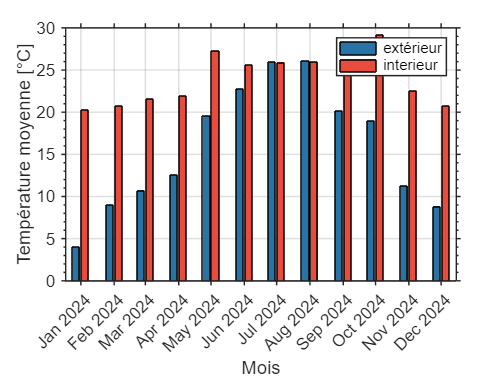

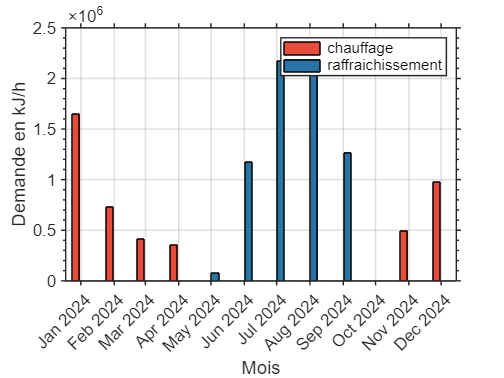

NbJofHeating =    155   151   127   151   135


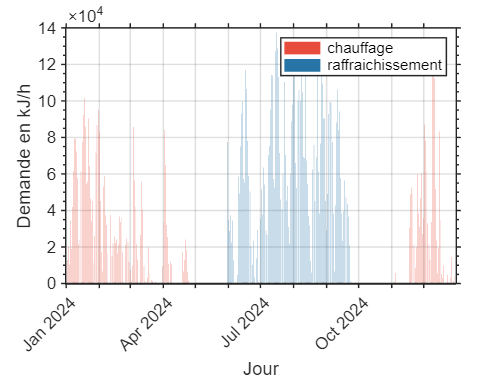

    {'DataDossier6'}



DatasetOut = 8760×8 timetable
            Time            TRNSys_TIME    Temperature_ext_C    Temperature_int_C    Temperature_op_C    QHeat_kJ_h    QHeat_kWh    QCool_kJ_h    QCool_kWh
    ____________________    ___________    _________________    _________________    ________________    __________    _________    __________    _________

    01-Jan-2024 01:00:00         1               12.24                   20                   20                0             0         0             0    
    01-Jan-2024 02:00:00         2              12.155                   20               19.838           829.77       0.23049         0             0    
    <

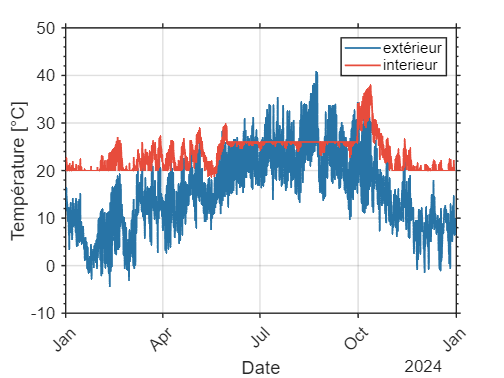

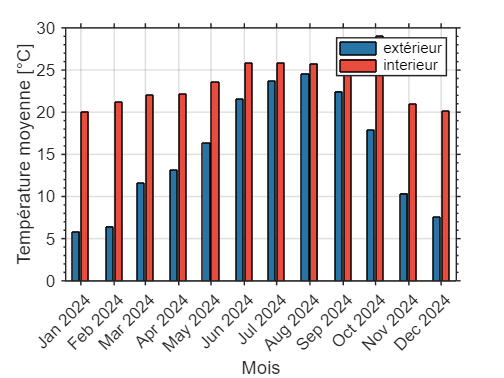

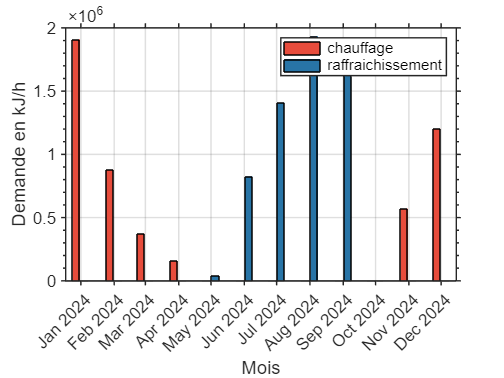

NbJofHeating =    155   151   127   151   135   152


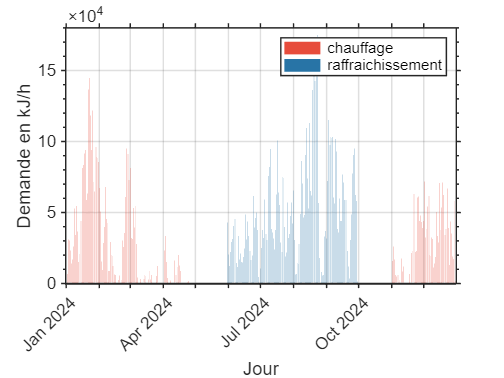

    {'DataDossier7'}



DatasetOut = 8760×8 timetable
            Time            TRNSys_TIME    Temperature_ext_C    Temperature_int_C    Temperature_op_C    QHeat_kJ_h    QHeat_kWh    QCool_kJ_h    QCool_kWh
    ____________________    ___________    _________________    _________________    ________________    __________    _________    __________    _________

    01-Jan-2024 01:00:00         1                6.37                   20                   20                0             0         0             0    
    01-Jan-2024 02:00:00         2               6.275                   20               19.743           1416.8       0.39357         0             0    
    <

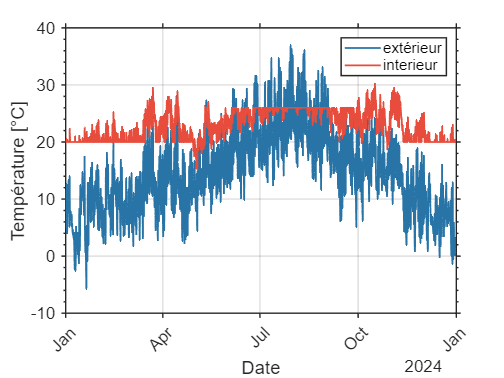

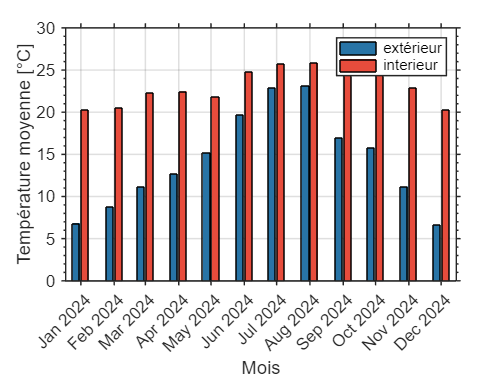

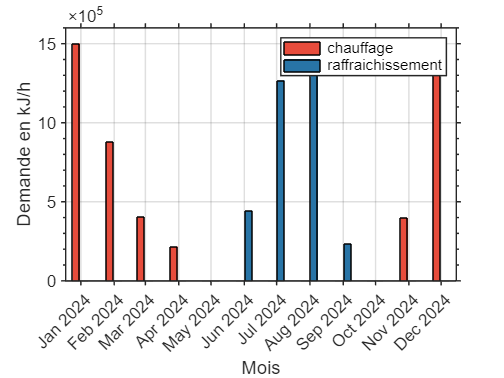

NbJofHeating =    155   151   127   151   135   152   144


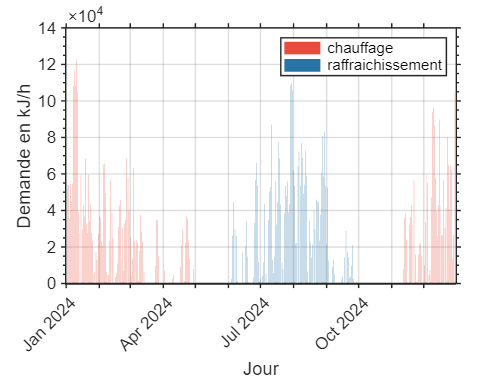

% Boucle
lg = length(DataNameInsideStruct);
for i = 1:lg

% Données utilisées
disp(DataNameInsideStruct(i))

% Affichage des données
DatasetOut = TheStructure.(DataNameInsideStruct{i})


### Variation de température

figure(i)

ParameterValues = 20


% Courbe de température
PlotT = plot(DatasetOut.Time,[DatasetOut.Temperature_ext_C DatasetOut.Temperature_int_C],"LineWidth",1.5);
grid on
ax = gca;
ax.TickDir = "out";
ax.FontSize = 14;       % set(ax,'TickDir','out','FontSize',14)
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.LineWidth = 1.2;
ax.XAxis.TickLabelRotation = 45;

% Label and Legend
xlabel("Date")
ylabel("Température [°C]")
legend("extérieur","interieur")

% Palette de couleur
PS = PLOT_STANDARDS();

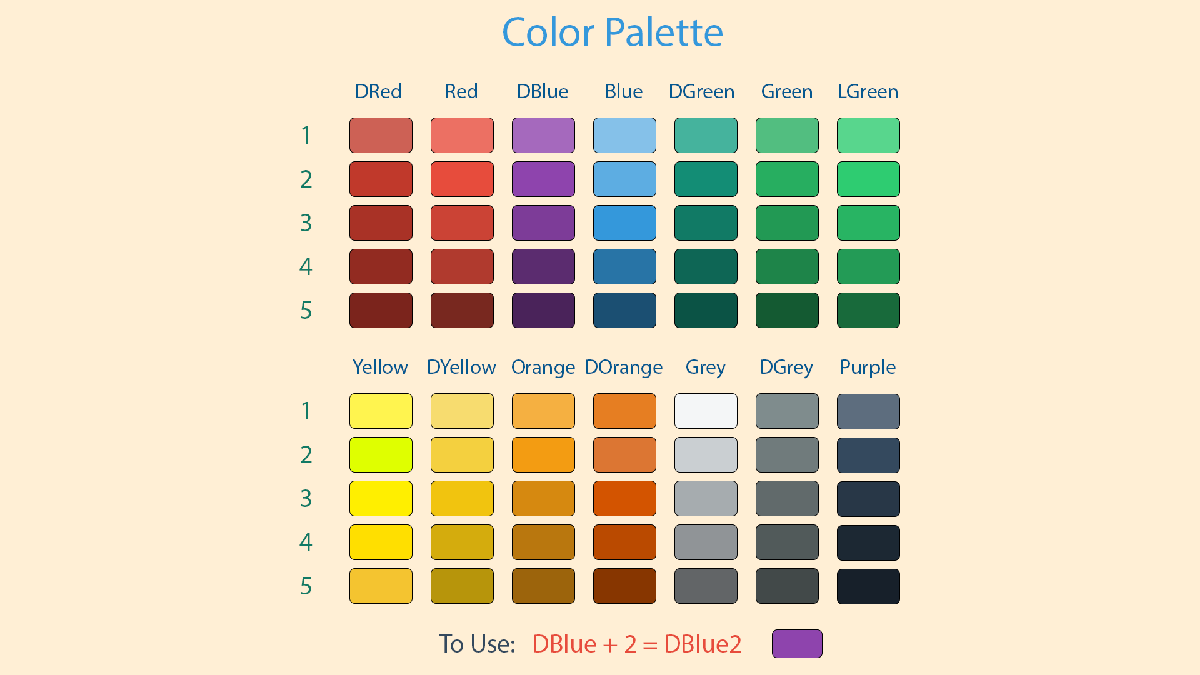

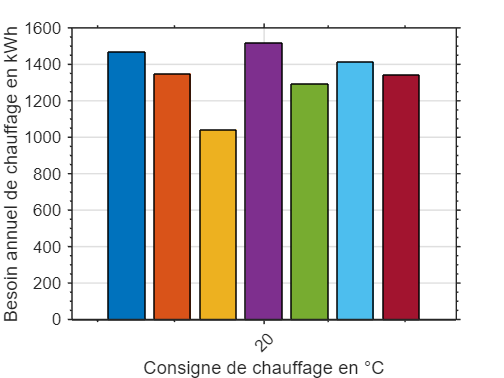

PlotT(1).Color = PS.Blue4;
PlotT(2).Color = PS.Red2;

grid on

% Moyenne mensuelle
figure(i+lg)
MoyMonth = retime(DatasetOut,'monthly','mean');
barT = bar(MoyMonth.Time,[MoyMonth.Temperature_ext_C MoyMonth.Temperature_int_C]);


% Axe
ax = gca;
ax.TickDir = "out";
ax.FontSize = 14;       % set(ax,'TickDir','out','FontSize',14)
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.LineWidth = 1.2;
ax.XAxis.TickLabelRotation = 45;

% Label and Legend
xlabel("Mois")
ylabel("Température moyenne [°C]")
legend(" extérieur"," interieur")

% Palette de couleur
% PS = PLOT_STANDARDS();
barT(1).FaceColor = PS.Blue4;
barT(2).FaceColor = PS.Red2;

grid on


### Demande de chauffage et de raffraichissement

% Chauffage par mois
figure(i+2*lg)
% barQH = bar(MoyMonth.Time,[MoyMonth.QHeat_kJ_h MoyMonth.QCool_kJ_h]);

SumMonth = retime(DatasetOut,'monthly','sum');
barQH = bar(SumMonth.Time,[SumMonth.QHeat_kJ_h SumMonth.QCool_kJ_h]);

% Axe
ax = gca;
ax.TickDir = "out";
ax.FontSize = 14;       % set(ax,'TickDir','out','FontSize',14)
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.LineWidth = 1.2;
ax.XAxis.TickLabelRotation = 45;

% Label and Legend
xlabel("Mois")
ylabel("Demande en kJ/h")
legend(" chauffage"," raffraichissement")

% Palette de couleur
% PS = PLOT_STANDARDS();
barQH(2).FaceColor = PS.Blue4;
barQH(1).FaceColor = PS.Red2;

grid on

% Chauffage par jour
figure(i+3*lg)
% barQH = bar(MoyMonth.Time,[MoyMonth.QHeat_kJ_h MoyMonth.QCool_kJ_h]);

SumDay = retime(DatasetOut,'daily','sum');
NbJofHeating(i) = sum(SumDay.QHeat_kWh > 0)

barQH = bar(SumDay.Time,[SumDay.QHeat_kJ_h SumDay.QCool_kJ_h]);

% Axe
ax = gca;
ax.TickDir = "out";
ax.FontSize = 14;       % set(ax,'TickDir','out','FontSize',14)
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.LineWidth = 1.2;
ax.XAxis.TickLabelRotation = 45;

% Label and Legend
xlabel("Jour")
ylabel("Demande en kJ/h")
legend(" chauffage"," raffraichissement")

% Palette de couleur
% PS = PLOT_STANDARDS();
barQH(2).FaceColor = PS.Blue4;
barQH(1).FaceColor = PS.Red2;

grid on

end

%

## Résultat de l'etude parametrique (cas de la température de consigne)

% Définition du paramètre étudié
ParameterValues = 20    % 18:1:24;                  % CECI doit être fait au début du script !!! à corriger

barTC = zeros(1,length(ParameterValues));

for i = 1:length(DataNameInsideStruct)

    DatasetOut = TheStructure.(DataNameInsideStruct{i});

    SumY = retime(DatasetOut,"yearly","sum");
    SumQH = SumY(1,"QHeat_kWh");
    
    barTC(i) = SumQH.QHeat_kWh;

end

bar(ParameterValues,barTC)

% Axe
ax = gca;
ax.TickDir = "out";
ax.FontSize = 14;       % set(ax,'TickDir','out','FontSize',14)
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.LineWidth = 1.2;
ax.XAxis.TickLabelRotation = 45;

% Label and Legend
xlabel("Consigne de chauffage en °C")
ylabel("Besoin annuel de chauffage en kWh")
grid on

## Tableau des différences de conso en % de 18°C à 24°C

% TransitionConsigne = [1820;2022;2224];
% 
% DiffConso(1,1) = (barTC(3)-barTC(1))/barTC(1)*100;
% 
% DiffConso(2,1) = (barTC(5)-barTC(3))/barTC(3)*100;
% 
% DiffConso(3,1) = (barTC(7)-barTC(5))/barTC(5)*100;
% 
% TablePourcentage = table(TransitionConsigne,DiffConso)

## Tableau barTC

% Tconsigne = 18:1:24;
% Tconsigne = Tconsigne';
% ConsoAnnuelle = barTC';
% TablebarTC = table(Tconsigne,ConsoAnnuelle)
